# Computing a controller using a discrete-time tuning method such that the closed loop's settling time is 10s

### Compute and declare my transfer function

The transfer function has the following form:


$$H_f \left(s\right)=\frac{K_f }{s\left(T_f s+1\right)}$$


Knowing that my values are Kf = 4 and  Tf = 8, the function becomes:


$$H_f \left(s\right)=\frac{4}{s\left(8s+1\right)}$$


I declare my transfer function in code:

Kf = 4;
Tf = 8;
Hf = tf(Kf,[Tf 1 0]);

The settling time for the closed loop should be 10s.

ts = 10;

Choose a sampling period (half the smallest constant):

Ts = 0.5;

Calculate the discrete transfer function:

Hfz = c2d(Hf,Ts,'zoh');

To calculate the imposed closed loop transfer function we first need to calculate T.

T = ts/4;

The imposed close loop transfer function becomes:

Ho = tf(1, [T, 1]);

Calculate the discrete imposed closed loop transfer function.

Hoz = c2d(Ho,Ts,'zoh')

Hoz =
 
    0.1813
  ----------
  z - 0.8187
 
Sample time: 0.5 seconds
Discrete-time transfer function.



Now we calculate the controller:

Hrz = minreal(1/Hfz*Hoz/(1-Hoz))

Hrz =
 
  2.961 z - 2.782
  ---------------
    z + 0.9794
 
Sample time: 0.5 seconds
Discrete-time transfer function.



Calculate the final closed loop transfer function:

finalHoz = minreal(Hrz*Hfz/(1+Hrz*Hfz))

finalHoz =
 
  0.1813 z^4 + 0.01449 z^3 - 0.3333 z^2 - 0.01333 z + 0.1534
  -----------------------------------------------------------
  z^5 - 0.7388 z^4 - 1.904 z^3 + 1.432 z^2 + 0.9067 z - 0.693
 
Sample time: 0.5 seconds
Discrete-time transfer function.



%step(finalHoz)

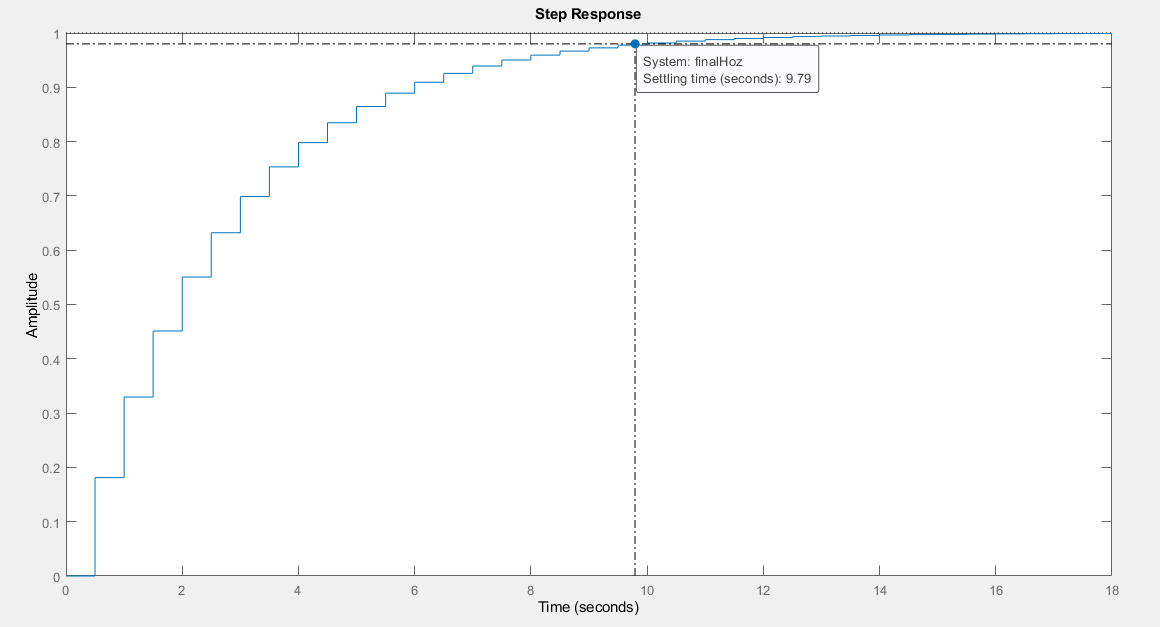

I try to eliminate ringing:

Hrz.Denominator{1}(1,2) = Hrz.Denominator{1}(1,1) + Hrz.Denominator{1}(1,2);
Hrz.Denominator{1}(1,1) = 0

Hrz =
 
  2.961 z - 2.782
  ---------------
       1.979
 
Sample time: 0.5 seconds
Discrete-time transfer function.



Calculate the final closed loop transfer function again:

finalHoz = minreal(Hrz*Hfz/(1+Hrz*Hfz))

finalHoz =
 
  0.0839 z^3 - 0.07546 z^2 - 0.08034 z + 0.07251
  ----------------------------------------------
        z^3 - 2.713 z^2 + 2.449 z - 0.7359
 
Sample time: 0.5 seconds
Discrete-time transfer function.



%step(finalHoz)